# Getting Started with M-M.E.S.S.

## Description

The M-M.E.S.S. toolbox provides solvers for  large-scale, sparse, symmetric linear and quadratic matrix equations. These can be algebraic and differential equations and the solvers are in their core all based on the low-rank ADI method.  M-M.E.S.S. can be seen as the successor to the LyaPack toolbox with an improved formulation of the ADI, that now properly supports generalized state space systems, but also special structured DAEs. It features additional solvers for differential equations, improved shift parameter computation and a guarantee to compute real low-rank factorizations, but follows the same general philosophy of user supplied functions that the LyaPack toolbox used.

## System Requirements

Runs on MATLAB R2014b and later. For some solvers the availablility of the Control System Toolbox is beneficial.

## Features

- large-scale algebraic Lyapunov equations (mess_lyap, mess_lradi)

- large-scale algebraic Riccati equations (mess_care, mess_lrnm, mess_lrri, mess_lrradi)

- large-scale differential Riccati equations (mess_bdf_dre, mess_rosenbrock_dre, mess_splitting_dre)

- model order reduction (mess_balanced_truncation, mess_square_root_method, mess_tangential_IRKA)

All of them for standard state space systems, second order systems and differential algebraic equation systems allowing implicit index-reduction. 

## M-M.E.S.S. philosophy and equation structures

To learn the basics about the philosophy behind the implementation of our solvers and the exact representation of the matrix equations check:

help mess

 
   ######################################################################
   #                                                                    #
   #          M-M.E.S.S. - Matrix Equations, Sparse Solvers             #
   #                                                                    #
   ######################################################################
 
   version 2.1
  
   The M-M.E.S.S. toolbox is intended for the solution of symmetric
   linear and quadratic, differential and algebraic matrix
   equations with real, large, and sparse (or sparse + low-rank)
   coefficient matrices in the linear terms, low-rank quadratic and
   constant terms, and low-rank solutions.  
  
   Using the user supplied functions (usfs) framework,
   M-M.E.S.S. enables the solution of equations for several
   system structures. While implicitly M-M.E.S.S. always treats a
   system 
       . 
     E x(t) = A x(t) + B u(t),                                 (1)
       y(t) = C x(t),
 
   with

For further information about the user supplied functions we recommend reading:

help mess_usfs

 
   ######################################################################
   #                                                                    #
   #         M-M.E.S.S. USFS - the user supplied function system        #
   #                                                                    #
   ######################################################################
 
   All operations with the implicit matrices (see (1) below) E, A, and
   (A + p E) regarding multiplication and solution of linear systems
   are implemented via user supplied functions used via function
   handles in the oper structure. The USFS section in `help mess`
   describes the sets of function handles shipped with M-M.E.S.S. and
   what types of systems they implement.
  
   Here, we describe which functions are mandatory, which
   additional ones are optional and how they can be used with the
   M-M.E.S.S. 'operatormanager' that generates the corresponding
   'oper' structure.
 
   All operations in M-M.E.S.

## Examples

We first load the Oberwolfach Rail example ([https://morwiki.mpi-magdeburg.mpg.de/morwiki/index.php/Steel_Profile](https://morwiki.mpi-magdeburg.mpg.de/morwiki/index.php/Steel_Profile)) 

eqn = mess_get_linear_rail(1); %change the number between 0 and 5 to get other sizes
E = eqn.E_;
A = eqn.A_; 
B = eqn.B; 
C = eqn.C;

## **Solutions to Lyapunov and Riccati equations**

For a simple standard (E, A, B, C) input output system with sparse E, A and thin rectangular B and C like the rail, simply call :

Zl = mess_lyap(A,B,[],[],E);

to compute, e.g., a controlability Gramian factor Zl. 

Similarly, 

[Zr, K] = mess_care(A, B, C, [], E);

can be used to compute a low-rank factor  Zr for the stabilizing solution of the linear quadratic regulator problems algebraic Riccati equation and the corresponding feedback gain matrix K. 

For structured problems and to take control of the soultion process via the many process parameters, one needs to run one of the low level solvers listed in the 'Features' section above. Check the DEMOS folder for various examples and consult the help texts of the single methods for the available parameters. 

## Model Order Reduction

To reduce the above model by Balanced truncation to at most order 15 with a desired error of 1e-5 use:

   -0.1705
   -0.1161
   -0.0846
   -0.0398
   -0.0312
   -0.0291

ADI Shifts:
   -0.1705
   -0.1161
   -0.0846
   -0.0398
   -0.0312
   -0.0291

ADI step:    1 normalized residual: 6.339052e-01 relative change in Z: 1.000000e+00
ADI step:    2 normalized residual: 4.528296e-01 relative change in Z: 4.970393e-01
ADI step:    3 normalized residual: 3.839213e-01 relative change in Z: 4.359048e-01
ADI step:    4 normalized residual: 2.945325e-01 relative change in Z: 4.279526e-01
ADI step:    5 normalized residual: 2.488714e-01 relative change in Z: 3.775197e-01
ADI step:    6 normalized residual: 2.147136e-01 relative change in Z: 3.154944e-01
updating shifts
   -0.0115
   -1.2419
   -0.0002
   -0.1147
   -0.0013
   -0.3276

ADI step:    7 normalized residual: 1.831227e-01 relative change in Z: 4.029865e-01
ADI step:    8 normalized residual: 1.781628e-01 relative change in Z: 7.941409e-02
ADI step:    9 normalized residual: 7.770650e-02 relative change in Z: 8.390174e-01
ADI step:   10 

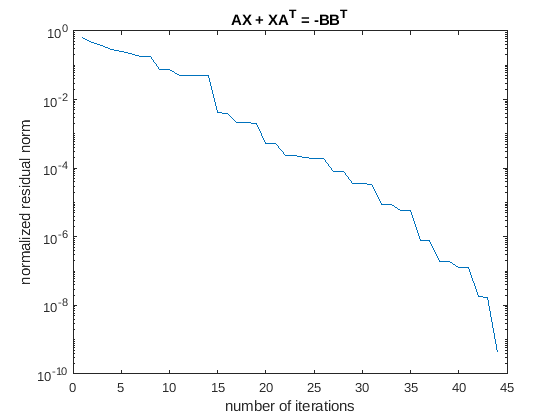

size outB.Z:


ans =         1357         308


ADI Shifts:
   -0.1705
   -0.1161
   -0.0846
   -0.0398
   -0.0312
   -0.0291

ADI step:    1 normalized residual: 3.242482e-01 relative change in Z: 1.000000e+00
ADI step:    2 normalized residual: 1.727837e-01 relative change in Z: 4.698305e-01
ADI step:    3 normalized residual: 1.009399e-01 relative change in Z: 3.047021e-01
ADI step:    4 normalized residual: 5.000172e-02 relative change in Z: 2.815238e-01
ADI step:    5 normalized residual: 2.525716e-02 relative change in Z: 1.956559e-01
ADI step:    6 normalized residual: 1.581945e-02 relative change in Z: 1.404626e-01
updating shifts
   -0.0432
   -0.0021
   -0.8998
   -0.2034
   -0.0086
   -0.5109

ADI step:    7 normalized residual: 1.190813e-02 relative change in Z: 8.953575e-02
ADI step:    8 normalized residual: 4.109976e-03 relative change in Z: 1.964764e-01
ADI step:    9 normalized residual: 3.291157e-03 relative change in Z: 5.306784e-02
ADI step:   10 normalized residual: 3.218579e-03 relative change in Z: 1.890279e-0

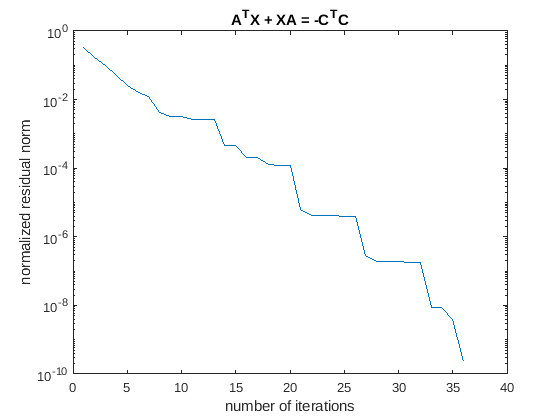

size outC.Z:


ans =         1357         216


reduced system order: 15  (max possible/allowed: 216/15)

Computing TFMs of original and reduced order systems and MOR errors

 Step  10 / 100
 Step  20 / 100
 Step  30 / 100
 Step  40 / 100
 Step  50 / 100
 Step  60 / 100
 Step  70 / 100
 Step  80 / 100
 Step  90 / 100
 Step 100 / 100



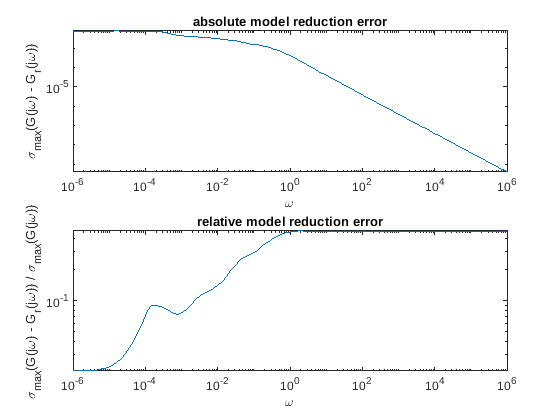

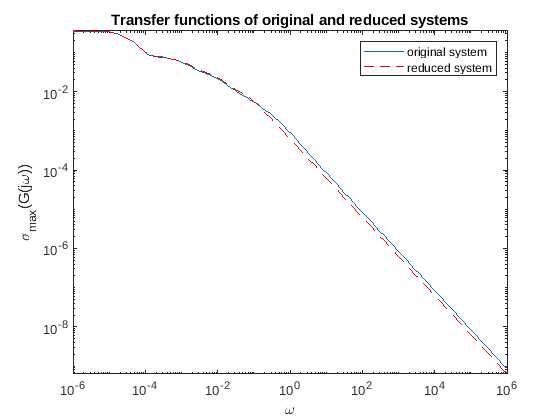

[Abt, Bbt, Cbt] = mess_balanced_truncation(E,A,B,C,15,1e-5,3);

Note that our implementation will always compute a standard state space model with Er being the identity. Analogously, for a tangential IRKA approximation of order 15, with logspaced initial shifts, call:

IRKA step   1, rel. chg. shifts = 1.729502e+01 , rel. H2-norm chg. ROM = 1.000000e+00


IRKA step   2, rel. chg. shifts = 5.091970e+00 , rel. H2-norm chg. ROM = Inf
IRKA step   3, rel. chg. shifts = 2.257340e+00 , rel. H2-norm chg. ROM = 9.971688e-01


IRKA step   4, rel. chg. shifts = 1.430068e+00 , rel. H2-norm chg. ROM = Inf


IRKA step   5, rel. chg. shifts = 1.699161e+01 , rel. H2-norm chg. ROM = Inf
IRKA step   6, rel. chg. shifts = 1.726075e+01 , rel. H2-norm chg. ROM = 5.452287e+00
IRKA step   7, rel. chg. shifts = 8.785304e-01 , rel. H2-norm chg. ROM = 2.150032e-01
IRKA step   8, rel. chg. shifts = 1.697561e+00 , rel. H2-norm chg. ROM = 1.011336e-01
IRKA step   9, rel. chg. shifts = 1.810090e-01 , rel. H2-norm chg. ROM = 5.423842e-02
IRKA step  10, rel. chg. shifts = 5.129246e-01 , rel. H2-norm chg. ROM = 4.205960e-02
IRKA step  11, rel. chg. shifts = 3.321398e-01 , rel. H2-norm chg. ROM = 2.808709e-02
IRKA step  12, rel. chg. shifts = 4.314042e-02 , rel. H2-norm chg. ROM = 1.658308e-02
IRKA step  13, rel. chg. shifts = 1.775381e-02 , rel. H2-norm chg. ROM = 1.257409e-02
IRKA step  14, rel. chg. shifts = 1.793332e-02 , rel. H2-norm chg. ROM = 1.400935e-02
IRKA step  15, rel. chg. shifts = 1.489474e-02 , rel. H2-norm chg. ROM = 1.826392e-02
IRKA step  16, rel. chg. shifts = 1.233513e-02 , rel. H2-norm c

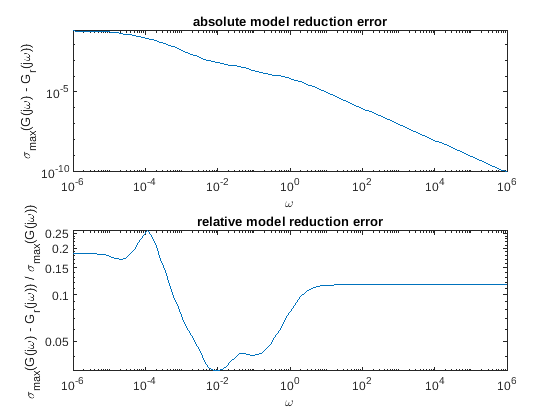

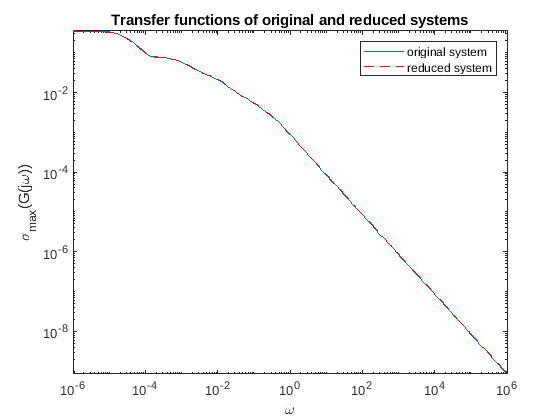

opts.irka.r = 15;
opts.irka.info = 2;

opts.irka.init = 'logspace';

[Ei, Ai, Bi, Ci] = mess_tangential_irka(E,A,B,C,opts);

Again many more model order reduction examples can be found in the DEMOS folder. 